# Develop differential equations for the cart-pole system

clear variables

addpath("~/ml-plot-utils/")

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end
plot_dir = 'plots';
if ~isfolder(plot_dir)
    mkdir(plot_dir)
end

## Description of system

The diagram and derivations below are based on:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

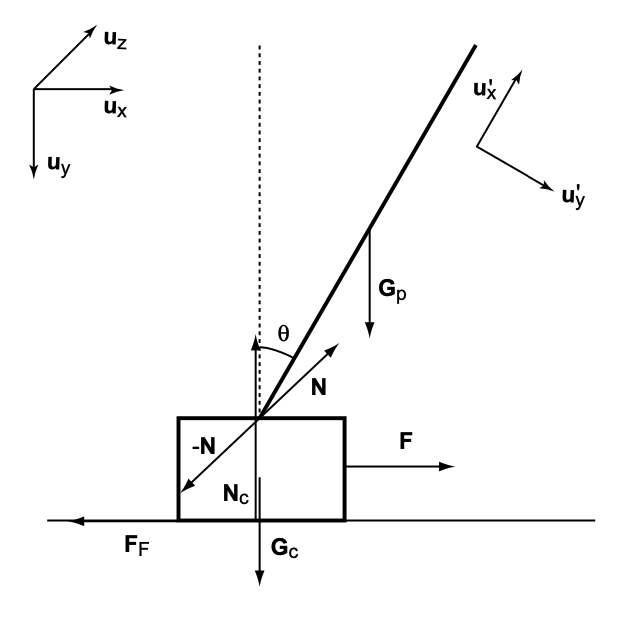

Note: Here, I will replace ${{\mathbf{u}}^{\prime } }_x$ and ${{\mathbf{u}}^{\prime } }_y$ with ${\mathbf{u}}_r$ and ${\mathbf{u}}_t$ to avoid confusion.

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of arm (clockwise from vertical up position) $\theta \left(t\right)$

- Angular velocity of cable$\dot{\;\theta \;} \left(t\right)$ (clockwise)

Other variables

- Upwards force on cart by track $N_c \left(t\right)$ (+ve upwards)

- Force exerted on arm by cart in x-direction $N_x \left(t\right)$ (+ve to right)

- Force exerted upwards on arm by cart (opposite to y-direction) $N_y \left(t\right)$ (+ve upwards)

- Frictional force exerted on cart by track $F_f \left(t\right)$ (+ve to left)

- Aerodynamic drag force on load opposite to x-direction $F_{d,x} \left(t\right)$(+ve to left)

- Aerodynamic drag force on load opposite to y-direction $F_{d,y\;} \left(t\right)$(+ve upwards)

Potential manipulatable input variables

- Horizontal driving force on cart $F\left(t\right)$

Potential disturbance input variables

- Horizontal wind velocity $v_{w,x} \left(t\right)$ - NOT YET IMPLEMENTED

Parameters

- Arm length $L$

- Cart mass $m_c$

- Pendulum mass $m_p$

- Acceleration due to gravity $g$

- Coefficient of friction for cart on track $\mu_c$

- Radius of the object at the end of the pole, $r$ (if it were a sphere)

- Aerodynamic drag coefficient of the object at the end of the pole $c_d$

- Mass density of air $\rho_a$

## Derivation of equations

% Define symbolic variables
syms x(t) theta(t) N_c(t) F_f(t) F_d(t) N_x(t) N_y(t) v_x(t) v_y(t) F
% Define symbolic constants
syms L m_c m_p g muc r c_d rho

Co-ordinate systems:

    ${\mathbf{u}}_x ,{\mathbf{u}}_y$: unit vectors in the x direction (to the right), and y direction (down).

    ${\mathbf{u}}_r ={\mathbf{u}}_x \sin \theta -{\mathbf{u}}_y \cos \theta$: unit vector in direction of pole (radially outwards)

    ${\mathbf{u}}_t ={\mathbf{u}}_x \cos \theta +{\mathbf{u}}_y \sin \theta$: unit vector perpendicular to pole (clockwise tangential direction)

Force balance on cart (cartesian vectors):

    $\mathbf{F}+{\mathbf{F}}_f +{\mathbf{G}}_c -\mathbf{N}+{\mathbf{N}}_c =m_c {\mathbf{a}}_c$                                   (3)

where:

    $\mathbf{F}=F{\mathbf{u}}_x$: external force applied to cart (to the right)

    ${\mathbf{F}}_f =-F_f {\mathbf{u}}_x$: friction force on cart due to track (to the left when $F_f$ is +ve)

    ${\mathbf{G}}_c =m_c g{\mathbf{u}}_y$: downwards force due to weight of cart

    $\mathbf{N}=N_x {\mathbf{u}}_x -N_y {\mathbf{u}}_y$: force on pole due to cart (upwards and to right when $N_x$ and $N_y$ are +ve)

    ${\mathbf{N}}_c ={-N}_c {\mathbf{u}}_y$: Force on cart by track (upwards when $N_c$ is +ve)

    ${\mathbf{a}}_c =\ddot{x} {\mathbf{u}}_x$ : acceleration of cart

Decompose (3) into x, y directions:

    $F-F_f -N_x =m_c \ddot{x}$                                                    (4)

    $m_c g+N_y -N_c =0$                                                    (5)

Coulomb friction model:

    $F_f =\mu_c |N_c |\textrm{sign}\left(\dot{x} \right)=\mu_c N_c \textrm{sign}\left(N_c \dot{x} \right)$                        (6)

Force balance on pole (cartesian vectors):

    $\mathbf{N}+{\mathbf{F}}_d +{\mathbf{G}}_p =m_p {\mathbf{a}}_p$                                                         (7)

where:

    ${\mathbf{F}}_d =-F_{d,x} {\mathbf{u}}_x -F_{d,y} {\mathbf{u}}_y$ : Aerodynamic drag force on load (in opposite direction to velocity of load relative to air)

    ${\mathbf{G}}_p =m_p g{\mathbf{u}}_y$ : weight of load (downwards)

    ${\mathbf{a}}_p$ : acceleration of the load

Absolute magnitude of drag force on load:

    
$$F_d =\frac{1}{2}\rho {|\mathbf{v}|}^2 c_d A=\frac{1}{2}\rho c_d A\left({\left(v_x +v_{w,x} \right)}^2 +v_y^2 \right)$$


where

    $\mathbf{v}=\left(v_x +v_{w,x} \right){\mathbf{u}}_x +v_y {\mathbf{u}}_y$: velocity of the load through the air

and

    
$$\begin{array}{l}
v_x =\dot{x} +L\dot{\theta} \cos \theta \;\\
v_y =L\dot{\theta} \sin \theta 
\end{array}$$


% x and y components of velocity of load through the air
eqn1 = v_x(t) == diff(x(t)) + L * diff(theta(t)) * cos(theta(t));
eqn2 = v_y(t) == L * diff(theta(t)) * sin(theta(t));

Magnitudes of x and y components of drag force on load:


$$F_{d,x} =\frac{1}{2}\rho c_d Av_x^2 =\frac{1}{2}\rho c_d {A\left(\dot{x} +\dot{L} \sin \theta +L\dot{\theta} \cos \theta \right)}^2$$



$$F_{d,y} =\frac{1}{2}\rho c_d Av_y^2 =\frac{1}{2}\rho c_d {A\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2$$


% Absolute magnitude of aerodynamic drag force
eqn3 = F_d(t) == 0.5 * rho * c_d * pi * r^2 * (v_x(t)^2 + v_y(t)^2)

$$eqn3 = F_{d}\left(t\right)=1.5708\,c_{d}\,r^{2}\,\rho \,\left({v_{x}\left(t\right)}^{2}+{v_{y}\left(t\right)}^{2}\right)$$

F_dx = sign(v_x) * 0.5 * rho * c_d * pi * r^2  * v_x(t)^2;  % TODO: Add wind as per above eqns
F_dy = sign(v_y) * 0.5 * rho * c_d * pi * r^2  * v_y(t)^2;

The acceleration of the load is due to the composed effects of:

- acceleration of cart

- acceleration due to rotation of pole with angular velocity $\omega =\dot{\theta} {\mathbf{u}}_z$

- angular acceleration of the pole $\varepsilon =\ddot{\theta} {\mathbf{u}}_z$

    ${\mathbf{a}}_p ={\mathbf{a}}_c +\varepsilon \times {\mathbf{r}}_p +\omega \times \left(\omega \times {\mathbf{r}}_p \right)$                            (8)

where:

    ${\mathbf{r}}_p =L\left(\sin \theta {\mathbf{u}}_y -\cos \theta {\mathbf{u}}_x \right)$ : position of centre of load relative to the pivot

Substitute (8) into (7) and decompose into x and y directions:

    $N_x =m_p \left(\ddot{x} +L\ddot{\theta} \cos \theta -L{\dot{\theta} }^2 \sin \theta \right)$                    (11)

% Horizontal (x) component of force on pole by cart (+ve to right)
eqn4 = N_x(t) == m_p * ( ...
    diff(x(t), 2) ...
    + L * diff(theta(t), 2) * cos(theta(t)) ...
    - L * diff(theta(t))^2 * sin(theta(t)) ...
)

$$eqn4 = N_{x}\left(t\right)=m_{p}\,\left(L\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-L\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)\right)$$

    $m_p g-N_y =m_p \left(L\ddot{\theta} \sin \theta +L{\dot{\theta} }^2 \cos \theta \right)$                (12)

% Vertical (y) component of force on pole by cart (upwards +ve)
eqn5 = N_y(t) == m_p * ( ...
    g ...
    - L * ( ...
        diff(theta(t), 2) * sin(theta(t)) ...
        + diff(theta(t))^2 * cos(theta(t)) ...
    ) ...
)

$$eqn5 = N_{y}\left(t\right)=m_{p}\,\left(g-L\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)\right)$$

% Friction force of track on cart (to the left when F_f(t) is positive)
eqn7 = F_f(t) == muc * N_c * sign(N_c * diff(x(t)))

$$eqn7(t) = F_{f}\left(t\right)=\mathrm{muc}\,\mathrm{sign}\left(N_{c}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)\,N_{c}\left(t\right)$$

Torque Balance of pole:

    
$$\mathbf{M}=\mathbf{I}\varepsilon +{\mathbf{r}}_p \times {\mathbf{a}}_c$$


where:

    $\mathbf{M}={\mathbf{r}}_p \times {\mathbf{G}}_p -{\mathbf{r}}_p \times {\mathbf{F}}_d$ : sum of non-inertial torques acting on the pole relative to the pivot.

    $\mathbf{I}=\frac{4}{3}m_p L^2$ : moment of inertia of the pole relative to the pivot

    ${\mathbf{r}}_p \times {\mathbf{a}}_c$ : torque generated by the inertial force caused by the acceleration of the cart.

Hence:

    
$$\left(m_p \mathrm{g}-F_{d,y} \right)\textrm{Lsin}\theta -F_{d,x} \textrm{Lcos}\theta =\frac{4}{3}m_p L^2 \ddot{\theta} +m_p \ddot{x} \textrm{Lcos}\theta$$


    $\left(m_p \mathrm{g}-F_{d,y} \right)\sin \theta -F_{d,x} \cos \theta =\frac{4}{3}m_p L\ddot{\theta} +m_p \ddot{x} \cos \theta$                (14)

From (4) and (11):

$\ddot{x} =\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-F_f }{m_c +m_p }$                        (15)

% Horizontal acceleration of cart (+ve to right)
eqn8 = diff(x(t), 2) == ( ...
    F ...
    + m_p * L * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
    - F_f(t) ...
) / (m_c + m_p)

$$eqn8 = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F-F_{f}\left(t\right)+L\,m_{p}\,\left(\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)}{m_{c}+m_{p}}$$

Rearrange (14):


$$\ddot{\theta} =\frac{1}{\frac{4}{3}m_p L}\left(\left(m_p \mathrm{g}-F_{d,y} \right)\sin \theta -\left(F_{d,x} +m_p \ddot{x} \right)\cos \theta \right)$$


% Angular acceleration
eqn9 = diff(theta(t), 2) == ( ...
        ( m_p * g - F_dy(t) ) * sin(theta(t)) ...
        - (F_dx + m_p * diff(x(t), 2)) * cos(theta(t)) ...
    ) / (4/3 * m_p * L)

$$eqn9(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{0.7500\,\left(\cos\left(\theta \left(t\right)\right)\,\left(m_{p}\,\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(v_{x}\left(t\right)\right)\,{v_{x}\left(t\right)}^{2}\right)-\sin\left(\theta \left(t\right)\right)\,\left(g\,m_{p}-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(v_{y}\left(t\right)\right)\,{v_{y}\left(t\right)}^{2}\right)\right)}{L\,m_{p}}$$

From (5), (6), and (12):

   
$$N_c =m_c g+N_y =m_c g+m_p g-F_{d,y} -m_p L\left(\ddot{\theta} \sin \theta +{\dot{\theta} }^2 \cos \theta \right)$$


        $=\left(m_c +m_p \right)g-\frac{1}{2}\rho c_d {A\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2 -m_p L\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)$        (17)

% Downward force on track by cart
eqn6 = N_c(t) == m_c .* g + N_y(t)

$$eqn6 = N_{c}\left(t\right)=N_{y}\left(t\right)+g\,m_{c}$$

To compute $\ddot{\theta}$ first, we need to substitute and re-arrange. Introduce (15) into (14) and re-arrange for $\ddot{\theta}$:


$$\ddot{\theta} =\frac{3}{4L}\left(\left(\mathrm{g}-\frac{\rho c_d A}{2m_p }{\left(\dot{L} \cos \theta +L\dot{\theta} \sin \theta \right)}^2 \right)\sin \theta -\left(\frac{\rho c_d A}{2m_p }{\left(\dot{x} +\dot{L} \sin \theta +L\dot{\theta} \cos \theta \right)}^2 +\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \mathrm{sign}\left(N_c \dot{x} \right)}{m_c +m_p }\right)\cos \theta \right)$$


eqn9_dash = isolate(subs(eqn9, {diff(x(t), t, t), N_c(t)}, {subs(rhs(eqn8), {F_f(t)}, {rhs(eqn7)}), rhs(eqn6)}), diff(theta(t), t, t))

$$eqn9\_dash = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{0.7500\,\left(\sin\left(\theta \left(t\right)\right)\,\left(g\,m_{p}-1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(v_{y}\left(t\right)\right)\,{v_{y}\left(t\right)}^{2}\right)-\cos\left(\theta \left(t\right)\right)\,\left(\frac{m_{p}\,\left(F-\mathrm{muc}\,\mathrm{sign}\left(N_{c}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)\,N_{c}\left(t\right)+L\,m_{p}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)}{m_{c}+m_{p}}+1.5708\,c_{d}\,r^{2}\,\rho \,\mathrm{sign}\left(v_{x}\left(t\right)\right)\,{v_{x}\left(t\right)}^{2}\right)\right)}{L\,m_{p}\,\left(\frac{0.7500\,m_{p}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}-1\right)}$$

Finally we get:


$$\ddot{x} =\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }$$


eqns = [eqn1 eqn2 eqn3 eqn4 eqn5 eqn6 eqn7 eqn8 eqn9];
vars = [x(t) theta(t) N_c(t) F_f(t) F_d(t) N_x(t) N_y(t) v_x(t) v_y(t)];
origVars = length(vars);

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      1     1     0     0     0     0     0     1     0
     0     1     0     0     0     0     0     0     1
     0     0     0     0     1     0     0     1     1
     1     1     0     0     0     1     0     0     0
     0     1     0     0     0     0     1     0     0
     0     0     1     0     0     0     1     0     0
     1     0     1     1     0     0     0     0     0
     1     1     0     1     0     0     0     0     0
     1     1     0     0     0     0     0     1     1


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ N_{c}\left(t\right)\\ F_{f}\left(t\right)\\ F_{d}\left(t\right)\\ N_{x}\left(t\right)\\ N_{y}\left(t\right)\\ v_{x}\left(t\right)\\ v_{y}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccccccc} F & L & c_{d} & g & m_{c} & m_{p} & \mathrm{muc} & r & \rho \end{array}\right)$$

Create the function handle. 

%f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho);

To save the DAE equations as a function script use this option

filename = 'craneDAEFunction.m';
f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho, 'File', filename);

### Set parameter values

Define parameter values as struct

params = struct();
params.F = 10;
params.L = 5;
params.c_d = 0.47;  % drag coefficient of a sphere = 0.47
params.g = 9.8;
params.m_c = 5;
params.m_p = 2;
params.muc = 0.2;
params.r = 1;  % radius of load
params.rho = 1.293;  % density of air (kg/m3)

### Checks of function calculations

DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ N_{c}\left(t\right)\\ F_{f}\left(t\right)\\ F_{d}\left(t\right)\\ N_{x}\left(t\right)\\ N_{y}\left(t\right)\\ v_{x}\left(t\right)\\ v_{y}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

% With no external force (F=0)
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);

% Equilibrium point 1: stationary at vertical up position
y0est = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1         y0     yp0
    ____________    ____    ___

    "x(t)"             0     0 
    "theta(t)"         0     0 
    "N_c(t)"        68.6     0 
    "F_f(t)"           0     0 
    "F_d(t)"           0     0 
    "N_x(t)"           0     0 
    "N_y(t)"        19.6     0 
    "v_x(t)"           0     0 
    "v_y(t)"           0     0 
    "Dxt(t)"           0     0 
    "Dthetat(t)"       0     0 



assert(all(abs(y0 - y0est) < 1e-13))
assert(all(abs(yp0) < 1e-16))

% Check at any x position
y0est = [2; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
assert(all(abs(y0 - y0est) < 1e-13))
assert(all(abs(yp0) < 1e-16))
y0est = [-3; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
assert(all(abs(y0 - y0est) < 1e-13))
assert(all(abs(yp0) < 1e-16))

% Equilibrium point 2: stationary at vertical down position
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0    
    ____________    ___________    __________

    "x(t)"                    0             0
    "theta(t)"           3.1416             0
    "N_c(t)"               68.6             0
    "F_f(t)"                  0             0
    "F_d(t)"        -5.6087e-46             0
    "N_x(t)"        -1.6366e-15             0
    "N_y(t)"               19.6             0
    "v_x(t)"         -3.943e-31             0
    "v_y(t)"                  0             0
    "Dxt(t)"                  0    3.2731e-16
    "Dthetat(t)"              0    2.2912e-16



assert(all(abs(y0 - y0est) < 1e-13))
assert(all(abs(yp0) < 1e-15))

% Check at any x position
y0est = [10; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0    
    ____________    ___________    __________

    "x(t)"                   10             0
    "theta(t)"           3.1416             0
    "N_c(t)"               68.6             0
    "F_f(t)"                  0             0
    "F_d(t)"        -5.6087e-46             0
    "N_x(t)"        -1.6366e-15             0
    "N_y(t)"               19.6             0
    "v_x(t)"         -3.943e-31             0
    "v_y(t)"                  0             0
    "Dxt(t)"                  0    3.2731e-16
    "Dthetat(t)"              0    2.2912e-16



assert(all(abs(y0 - y0est) < 1e-13))
assert(all(abs(yp0) < 1e-15))

% Accelerating downwards in horizontal right position
y0est = [
    0; pi/2; params.m_c*params.g; 0; 
    0.5*params.rho*params.c_d*pi*params.r^2*5^2; 
    0; 0; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0             yp0    
    ____________    ___________    ___________

    "x(t)"                    0              0
    "theta(t)"           1.5708              0
    "N_c(t)"               53.9              0
    "F_f(t)"                  0              0
    "F_d(t)"         1.7415e-35              0
    "N_x(t)"         6.4294e-16              0
    "N_y(t)"                4.9              0
    "v_x(t)"         5.0104e-34              0
    "v_y(t)"        -7.9597e-45              0
    "Dxt(t)"                  0    -1.2859e-16
    "Dthetat(t)"              0           1.47



assert(all(abs(yp0(1:9)) < 1e-16))
assert(abs(yp0(10)) < 1e-15 && yp0(11) > 0)

% Accelerating downwards in horizontal left position
y0est = [0; -pi/2; params.m_c*params.g; 0; 0; 0; 0; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0    
    ____________    ___________    __________

    "x(t)"                    0             0
    "theta(t)"          -1.5708             0
    "N_c(t)"               53.9             0
    "F_f(t)"                  0             0
    "F_d(t)"        -1.7314e-35             0
    "N_x(t)"        -6.4294e-16             0
    "N_y(t)"                4.9             0
    "v_x(t)"        -5.0104e-34             0
    "v_y(t)"        -1.1925e-44             0
    "Dxt(t)"                  0    1.2859e-16
    "Dthetat(t)"              0         -1.47



assert(all(abs(yp0(1:9)) < 1e-16))
assert(all(abs(yp0(1:9)) < 1e-15))
assert(abs(yp0(10)) < 1e-15 && yp0(11) < 0)

% Accelerates towards stable equilibrium
y0est = [0; 0.99*pi; (params.m_c + params.m_p)*params.g; 
    0; 0; 0; params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0           yp0   
    ____________    ___________    ________

    "x(t)"                    0           0
    "theta(t)"           3.1102           0
    "N_c(t)"             68.582           0
    "F_f(t)"                  0           0
    "F_d(t)"        -3.4218e-39           0
    "N_x(t)"           -0.41944           0
    "N_y(t)"             19.582           0
    "v_x(t)"        -6.9791e-34           0
    "v_y(t)"                  0           0
    "Dxt(t)"                  0    0.083888
    "Dthetat(t)"              0    0.058751



assert(all(yp0(1:9) == 0))
assert(yp0(10) > 0 && yp0(11) > 0)

% Accelerates towards stable equilibrium
y0est = [0; 1.01*pi; (params.m_c + params.m_p)*params.g; 
    0; 0; 0; params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0           yp0   
    ____________    __________    _________

    "x(t)"                   0            0
    "theta(t)"           3.173            0
    "N_c(t)"            68.582            0
    "F_f(t)"                 0            0
    "F_d(t)"        3.3132e-38            0
    "N_x(t)"           0.41944            0
    "N_y(t)"            19.582            0
    "v_x(t)"        1.3425e-31            0
    "v_y(t)"                 0            0
    "Dxt(t)"                 0    -0.083888
    "Dthetat(t)"             0    -0.058751



assert(all(yp0(1:9) == 0))
assert(yp0(10) < 0 && yp0(11) < 0)

% Accelerates away from unstable equilibrium
y0est = [0; 0.01*pi; (params.m_c + params.m_p)*params.g; 
    0; 0; 0; params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0   
    ____________    ___________    _________

    "x(t)"                    0            0
    "theta(t)"         0.031416            0
    "N_c(t)"             68.582            0
    "F_f(t)"                  0            0
    "F_d(t)"        -3.3132e-38            0
    "N_x(t)"            0.41944            0
    "N_y(t)"             19.582            0
    "v_x(t)"         1.1001e-31            0
    "v_y(t)"                  0            0
    "Dxt(t)"                  0    -0.083888
    "Dthetat(t)"              0     0.058751



assert(all(yp0(1:9) == 0))
assert(yp0(10) < 0 && yp0(11) > 0)

% Accelerates away from unstable equilibrium
y0est = [0; -0.01*pi; (params.m_c + params.m_p)*params.g;
    0; 0; 0; params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0   
    ____________    ___________    _________

    "x(t)"                    0            0
    "theta(t)"        -0.031416            0
    "N_c(t)"             68.582            0
    "F_f(t)"                  0            0
    "F_d(t)"        -3.7831e-38            0
    "N_x(t)"           -0.41944            0
    "N_y(t)"             19.582            0
    "v_x(t)"        -9.5004e-32            0
    "v_y(t)"                  0            0
    "Dxt(t)"                  0     0.083888
    "Dthetat(t)"              0    -0.058751



assert(all(yp0(1:9) == 0))
assert(yp0(10) > 0 && yp0(11) < 0)

% Moving downwards in horizontal right position
y0est = [
    0; 
    pi/2; 
    params.m_c*params.g; 
    0; 
    0.5*params.rho*params.c_d*pi*params.r^2*5^2; 
    0; 
    0; 
    0; 
    params.L*1; 
    0; 
    1];
yp0est = [0; 1; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0          yp0   
    ____________    __________    ________

    "x(t)"                   0           0
    "theta(t)"          1.5708           1
    "N_c(t)"            71.799           0
    "F_f(t)"                 0           0
    "F_d(t)"            23.865           0
    "N_x(t)"           -7.1429           0
    "N_y(t)"            22.799           0
    "v_x(t)"        3.0616e-16           0
    "v_y(t)"                 5           0
    "Dxt(t)"                 0      1.4286
    "Dthetat(t)"             1    -0.31985



assert(all(abs(y0(8:11) - y0est(8:11)) < 1e-15))
assert(all(abs(yp0(1:9) - yp0est(1:9)) < 1e-16))
%assert(yp0(10) > 0 && yp0(11) > 0)  TODO: Check if this should be slowing
%down

% Moving downwards in horizontal left position
y0est = [
    0; 
    3*pi/2; 
    params.m_c*params.g; 
    0; 
    0.5*params.rho*params.c_d*pi*params.r^2*5^2; 
    0; 
    0; 
    0; 
    params.L*1; 
    0; 
    -1];
yp0est = [0; -1; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0          yp0  
    ____________    __________    _______

    "x(t)"                   0          0
    "theta(t)"          4.7124         -1
    "N_c(t)"            71.799          0
    "F_f(t)"                 0          0
    "F_d(t)"            23.865          0
    "N_x(t)"            7.1429          0
    "N_y(t)"            22.799          0
    "v_x(t)"        9.1849e-16          0
    "v_y(t)"                 5          0
    "Dxt(t)"                 0    -1.4286
    "Dthetat(t)"            -1    0.31985



assert(all(abs(y0(8:11) - y0est(8:11)) < 1e-15))
assert(all(abs(yp0(1:9) - yp0est(1:9)) < 1e-16))
% assert(yp0(10) < 0 && yp0(11) < 0)  TODO: Check if this should be slowing

% With +ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, 10, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);

% Accelerates away from unstable equilibrium
y0est = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0           yp0   
    ____________    ___________    ________

    "x(t)"                    0           0
    "theta(t)"                0           0
    "N_c(t)"               68.6           0
    "F_f(t)"                  0           0
    "F_d(t)"        -1.5114e-34           0
    "N_x(t)"            0.90909           0
    "N_y(t)"               19.6           0
    "v_x(t)"         1.0088e-27           0
    "v_y(t)"                  0           0
    "Dxt(t)"                  0      1.8182
    "Dthetat(t)"              0    -0.27273



assert(all(yp0(1:9) == 0))
assert(yp0(10) > 0 && yp0(11) < 0)

% With -ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, -10, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);

% At vertical down position
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0          yp0   
    ____________    __________    ________

    "x(t)"                   0           0
    "theta(t)"          3.1416           0
    "N_c(t)"              68.6           0
    "F_f(t)"                 0           0
    "F_d(t)"        1.0264e-35           0
    "N_x(t)"          -0.90909           0
    "N_y(t)"              19.6           0
    "v_x(t)"        4.4181e-28           0
    "v_y(t)"                 0           0
    "Dxt(t)"                 0     -1.8182
    "Dthetat(t)"             0    -0.27273



assert(all(yp0(1:9) == 0))
assert(yp0(10) < 0 && yp0(11) < 0)

% Check cart-track friction force and drag force

% With no cart-track friction or drag
%F_DAE = @(t, Y, YP) f(t, Y, YP, F, L, c_d, g, m_c, m_p, muc, r, rho);
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, params.g, params.m_c, ...
    params.m_p, 0, params.r, params.rho);

% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 10; 0; 10; 0];
yp0est = [10; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0            yp0    
    ____________    ___________    __________

    "x(t)"                    0            10
    "theta(t)"           3.1416             0
    "N_c(t)"               68.6             0
    "F_f(t)"                  0             0
    "F_d(t)"                  0             0
    "N_x(t)"        -1.6366e-15             0
    "N_y(t)"               19.6             0
    "v_x(t)"                 10             0
    "v_y(t)"                  0             0
    "Dxt(t)"                 10    3.2731e-16
    "Dthetat(t)"              0    2.2912e-16



assert(all(abs(y0(4:5)) < 1e-16))
assert(all(abs(y0(8:11) - y0est(8:11)) < 1e-13))
assert(all(abs(y0 - y0est) < 1e-13))
assert(isequal(yp0(1:9), [10 0 0 0 0 0 0 0 0]'))
assert(all(abs(yp0(10:11)) < 1e-15))

% With drag force but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, 0, params.r, params.rho);

% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 1; 0; 1; 0];
yp0est = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1           y0         yp0  
    ____________    ________    _______

    "x(t)"                 0          1
    "theta(t)"        3.1416          0
    "N_c(t)"            68.6          0
    "F_f(t)"               0          0
    "F_d(t)"         0.95459          0
    "N_x(t)"        -0.65086          0
    "N_y(t)"            19.6          0
    "v_x(t)"               1          0
    "v_y(t)"               0          0
    "Dxt(t)"               1    0.13017
    "Dthetat(t)"           0    0.09112



assert(y0(4) == 0 && y0(5) > 0)
assert(y0(8) == 1 && y0(9) == 0)
assert(isequal(yp0(1:9), [1 0 0 0 0 0 0 0 0]'))
%assert(abs(yp0(10)) < 1e-15 && yp0(11) > 1e-15)  % TODO: Is yp0(10) wrong?

% With cart-track friction but no drag force
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, ...
    params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);

% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 1; 0; 1; 0];
yp0est = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1          y0         yp0   
    ____________    _______    ________

    "x(t)"                0           1
    "theta(t)"       3.1416           0
    "N_c(t)"           68.6           0
    "F_f(t)"          13.72           0
    "F_d(t)"              0           0
    "N_x(t)"        -1.2473           0
    "N_y(t)"           19.6           0
    "v_x(t)"              1           0
    "v_y(t)"              0           0
    "Dxt(t)"              1     -2.4945
    "Dthetat(t)"          0    -0.37418



assert(y0(4) > 0 && y0(5) == 0)
assert(isequal(yp0(1:9), [1 0 0 0 0 0 0 0 0]'))
assert(yp0(10) < -1e-15 && yp0(11) < -1e-15)

% With drag force and cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);

% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 
    params.m_p*params.g; 1; 0; 1; 0];
yp0est = [1; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1          y0         yp0   
    ____________    _______    ________

    "x(t)"                0           1
    "theta(t)"       3.1416           0
    "N_c(t)"           68.6           0
    "F_f(t)"          13.72           0
    "F_d(t)"        0.95459           0
    "N_x(t)"        -1.8981           0
    "N_y(t)"           19.6           0
    "v_x(t)"              1           0
    "v_y(t)"              0           0
    "Dxt(t)"              1     -2.3644
    "Dthetat(t)"          0    -0.28306



assert(isequal(yp0(1:9), [1 0 0 0 0 0 0 0 0]'))
assert(yp0(10) < -1e-15 && yp0(11) < -1e-15)

### Find initial condition

Create function for ode15i

params.F = 5;
F_DAE = @(t, Y, YP) f(t, Y, YP, params.F, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);
DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ N_{c}\left(t\right)\\ F_{f}\left(t\right)\\ F_{d}\left(t\right)\\ N_{x}\left(t\right)\\ N_{y}\left(t\right)\\ v_{x}\left(t\right)\\ v_{y}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)`, `theta(t)`.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
y0est = [-3; deg2rad(180 - 0); (params.m_c + params.m_p)*params.g; 
    0; 0; 0; 0; 0; 0; 0; 0];
% Their derivatives
yp0est = [0; 0; 0; 0; 0; 0; 0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 0 0 0 0 0 0 1 1]';
FIXED_YP0 = [0 0 0 0 0 0 0 0 0 0 0]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, FIXED_YP0, opt);
disp(table(string(DAEvars), y0, yp0))

        Var1            y0          yp0  
    ____________    __________    _______

    "x(t)"                  -3          0
    "theta(t)"          3.1416          0
    "N_c(t)"              68.6          0
    "F_f(t)"                 0          0
    "F_d(t)"        3.2414e-35          0
    "N_x(t)"           0.45455          0
    "N_y(t)"              19.6          0
    "v_x(t)"        1.1298e-28          0
    "v_y(t)"                 0          0
    "Dxt(t)"                 0    0.90909
    "Dthetat(t)"             0    0.13636



Draw initial position

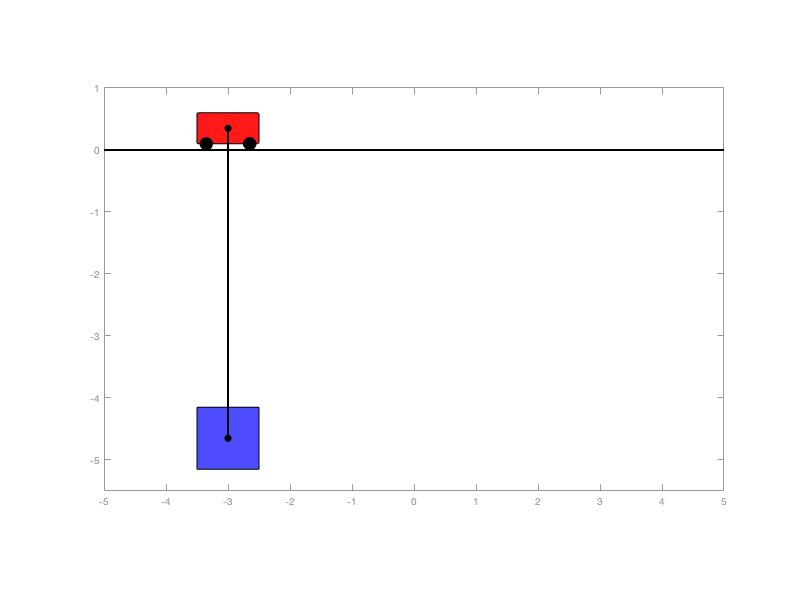

figure(1); clf
draw_crane(y0([1 3 2 4]),params)

### Solve DAEs Using ode15i

opt = odeset('RelTol', 10.0^(-5), 'AbsTol', 10.0^(-4));
[tSol, ySol] = ode15i(F_DAE, [0 3], y0, yp0, opt);

Plot solution

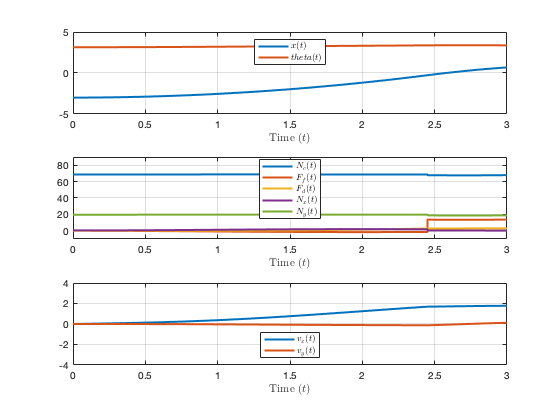

figure(2); clf
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);

% Group vars for plots
plot_select = {[1 2], [3 4 5 6 7], []};
plot_select{3} = ~ismember(1:numel(labels), cell2mat(plot_select(1:2)));

y_lims = {[-5 5], [-10 90], [-4 4]};

figure()
for i = 1:numel(plot_select)
    subplot(3,1,i)
    plot(tSol, ySol(:, plot_select{i}), 'LineWidth', 2)
    ylim(y_lims{i})
    legend(string2latex(labels(plot_select{i})), ...
        'Location', 'best', 'Interpreter', 'latex')
    grid on
    xlabel("Time ($t$)", 'Interpreter', 'latex')
end

filename = "test_sim_DAEs_crane.pdf";
save_fig_to_pdf(fullfile(plot_dir, filename))

### Save results to file

labels = arrayfun(@(i) char(DAEvars(i)), 1:numel(DAEvars), 'UniformOutput', false);
sim_results = array2table([tSol ySol], 'VariableNames', [{'t'} labels]);
filename = "crane_benchmark_sim.csv";
writetable(sim_results, fullfile(results_dir, filename))

### Solve using function script file

Solve the equations using the function script created by `daeFunction` above and check results are identical.

% Solve DAEs
F_DAE2 = @(t, Y, YP) craneDAEFunction(t, Y, YP, params.F, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);
[tSol2, ySol2] = ode15i(F_DAE2, [0 3], y0, yp0, opt);
assert(all(abs(tSol - tSol2) < 1e-8))
assert(max(ySol - ySol2, [], [1 2]) < 1e-8)

Solve using the edited function in crane_DAEs.m

% Solve DAEs
F_DAE2 = @(t, Y, YP) crane_DAEs(t, Y, YP, params);
[tSol2, ySol2] = ode15i(F_DAE2, [0 3], y0, yp0, opt);
assert(all(abs(tSol - tSol2) < 1e-8))

Arrays have incompatible sizes for this operation.

Related documentation

assert(max(ySol - ySol2, [], [1 2]) < 1e-8)